# Introduction to the Smartphone Coordinate System: Drawing your phones orientation in 3D

## Getting everything setup

**On your computer:**

- Get the MATLAB Support Package for [Android](https://de.mathworks.com/hardware-support/android-sensor.html?s_tid=AO_HS_info)/ [iOS Sensors](https://de.mathworks.com/hardware-support/iphone-sensor.html?s_tid=AO_HS_info)

**On your smartphone:**

- Download the MATLAB App for Android/iOS 

- Open the MATLAB App on your smartphone

- Login with the same Mathworks account as on your computer

- Go to the *Sensors *tab --> *More *--> enable *Sensor Access and * *Acquire Data in Background*

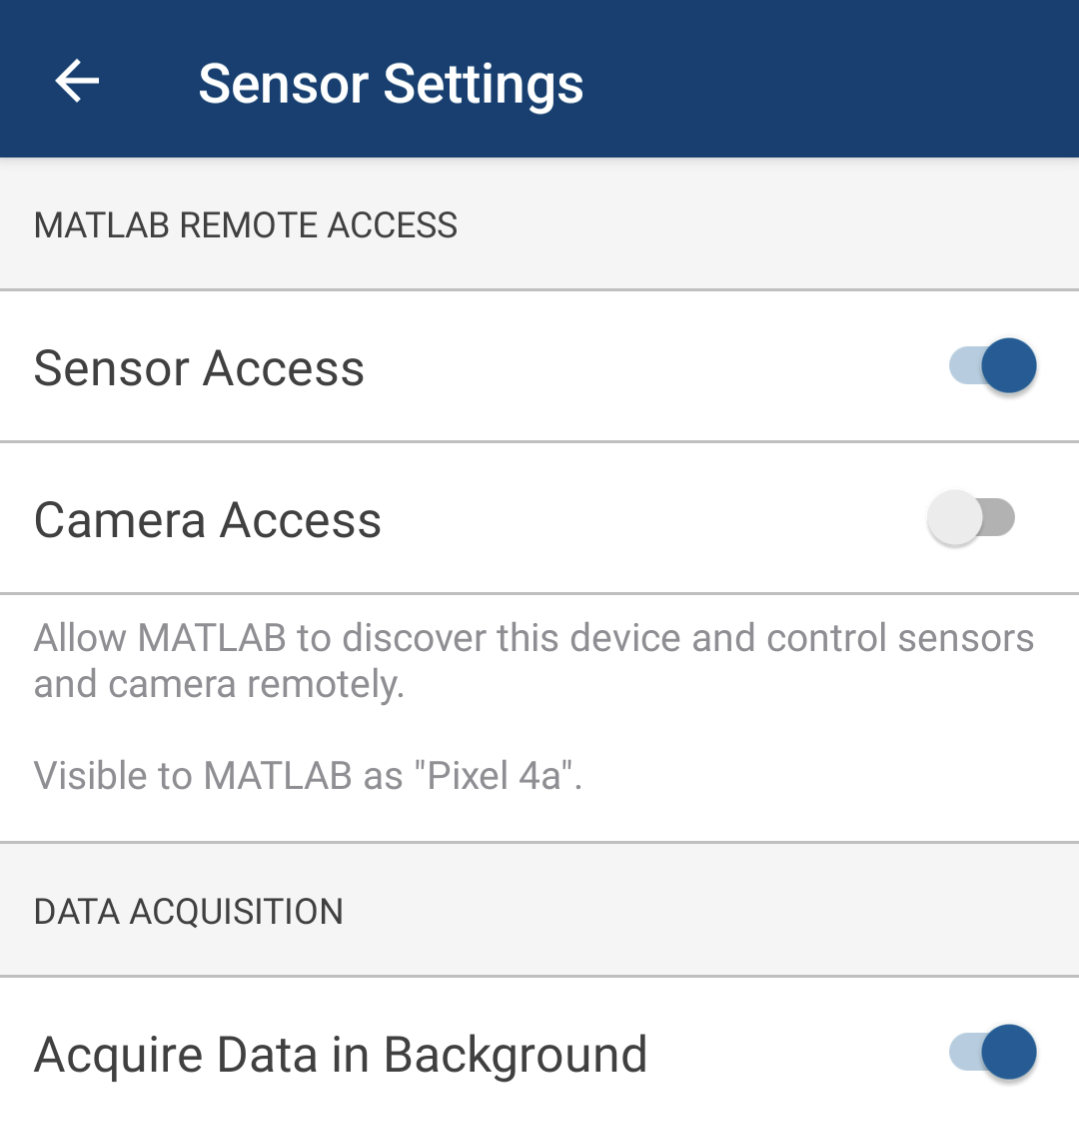

## Now lets try connecting your smartphone

For your convenience you can use the init_sensor function. The function will automatically try to connect you with your smartphone and start streaming the selected sensors into the mobile_data variable. We can enable the sensors we want to use by putting a one at the right position. Lets first activate the orientation sensor.

%First some initialization
clc
close all
clear
addpath([pwd, '\init']);
addpath([pwd, '\Functions'])

%init_sensors(AngularSnsEnbl, OrientSnsEnbl, AccelSnsEnbl, MagneticSnsEnbl, PosSnsEnbl)
mobile_data = init_sensors(0,1,0,0,0);

Trying to connect to mobile device via mathworks account...
Successfully connected to:
Pixel 4a
Successfully streaming Sensor Data!



%Define the Sample Rate [Hz]
mobile_data.SampleRate = 10;

After a couple of seconds, you should now see the object mobile_data appear in your workspace. Great! The mobile_data object now contains the live sensor data of your smartphone as long as the connection is not broken. If you loose the connection, for example when you close the app or turn off the screen on your smartphone, reopen the app and rerun the cell above.

## Lets beginn by plotting the orientation of your smartphone

The smartphone coordinate looks like this:

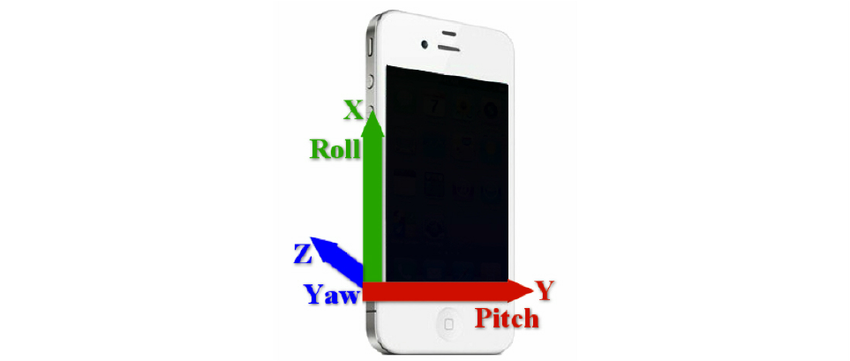

The orientation sensor estimates yaw, pitch and roll angles. The values are stored in the Orientation variable of the workspace, after the orientation sensor has been enabled in the cell above. Note that this is a left handed coordinate system with the z-Axis pointing downwards.

### Task 1.1: Plot the roll pitch and yaw of your smartphone and test the roll, pitch and yaw movement:

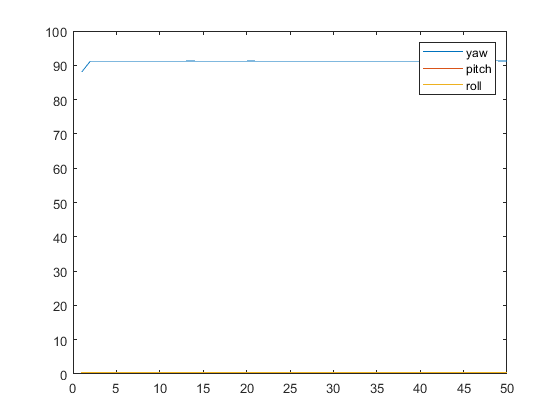

i_max = 50;

%Init
yaw = zeros(1,i_max);
pitch = zeros(1,i_max);
roll = zeros(1,i_max);


for i = 1:i_max
    
    %%%% Your code begins here
    
    yaw(1,i) =  mobile_data.Orientation(1);
    pitch(1,i) = mobile_data.Orientation(2);
    roll(1,i) =  mobile_data.Orientation(3);
    
    
    %%% Your code ends here
    
    plot(yaw(1,1:i));
    hold on
    plot(pitch(1,1:i));
    plot(roll(1,1:i));
    hold off
    legend('yaw','pitch','roll')
    
    drawnow
    
    pause(1/mobile_data.SampleRate);
    
    
end

## Great! However these line plots are not really visually satisfying. Lets try to create a plot that shows the orientation of your smartphone in 3D!

### We first define a fixed coordinate frame that matches our initial smartphone coordinate frame and plot it like this:

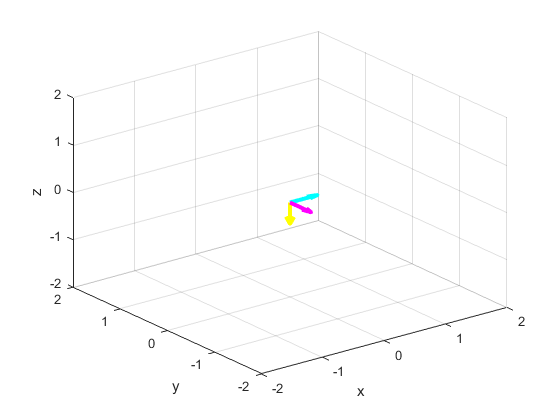

%Define world frame
world_frame = [1 0 0;
               0 -1 0; 
               0 0 -1];

world_frame_origin = [0; 0; 0];


%Plot world frame 
f = quiver3(world_frame_origin(1), world_frame_origin(2), world_frame_origin(3), world_frame(1,1)/2, world_frame(1,2)/2, world_frame(1,3)/2 ,'c', 'MaxHeadSize', 3, 'LineWidth', 3);
hold on
quiver3(world_frame_origin(1), world_frame_origin(2), world_frame_origin(3), world_frame(2,1)/2, world_frame(2,2)/2, world_frame(2,3)/2 ,'m', 'MaxHeadSize', 3, 'LineWidth', 3);
quiver3(world_frame_origin(1), world_frame_origin(2), world_frame_origin(3), world_frame(3,1)/2, world_frame(3,2)/2, world_frame(3,3)/2 ,'y', 'MaxHeadSize', 3, 'LineWidth', 3);
axis([-2 2 -2 2 -2 2]);
xlabel('x');
ylabel('y');
zlabel('z');

Note that this is aswell left handed coordinate system and matches the picture from the beginning.

### Now lets add our smartphone frame in the center

### Task 1.2: Add a smartphone frame that matches the world frame

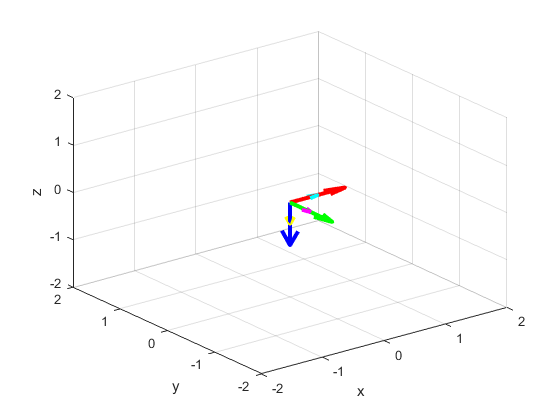

%Define world frame

%%% Your code begins here
smartphone_frame = [1 0 0;
                    0 -1 0; 
                    0 0 -1];

smartphone_frame_origin = [0; 0; 0];

%%% Your code ends here

%Plot smartphone frame
quiver3(smartphone_frame_origin(1), smartphone_frame_origin(2), smartphone_frame_origin(3), smartphone_frame(1,1), smartphone_frame(1,2), smartphone_frame(1,3) ,'r', 'MaxHeadSize', 3, 'LineWidth', 3);
quiver3(smartphone_frame_origin(1), smartphone_frame_origin(2), smartphone_frame_origin(3), smartphone_frame(2,1), smartphone_frame(2,2), smartphone_frame(2,3) ,'g', 'MaxHeadSize', 3, 'LineWidth', 3);
quiver3(smartphone_frame_origin(1), smartphone_frame_origin(2), smartphone_frame_origin(3), smartphone_frame(3,1), smartphone_frame(3,2), smartphone_frame(3,3) ,'b', 'MaxHeadSize', 3, 'LineWidth', 3);
hold off

## Now to the interesting part: Rotating the smarphone frame according to yaw, pitch and roll

This is a farely common problem in all of engineering and computer science. Rotations between two coordinate frames are commonly described with the Rotation Matrix R. We are looking for an R such that **smartphone_frame = R * world_frame**.

Since we have roll, pitch, and yaw given can calculate R by using the rotation matrices in 3D. We then calculate and plot the smartphone_frame.

while 1
    %Convert yaw, pitch, roll from DEG to RAD
    yaw = -deg2rad(mobile_data.Orientation(1));
    pitch = deg2rad(mobile_data.Orientation(2));
    roll = -deg2rad(mobile_data.Orientation(3));
    
    %%% Your code begins here
    
    %Calculate R by multiplying rotation-matrices
    R = Rx(roll)*Ry(pitch)*Rz(yaw);
    
    
    %%% Your code ends here
    
    %Apply Rotation to Smartphone Frame
    smartphone_frame = R*world_frame;
    
    %Plot smartphone frame and world frame
    plot_frames(smartphone_frame,smartphone_frame_origin,world_frame,world_frame_origin);
end

### The smartphone frame will be initially alligned with the earths magnetic field, since the magnetometer is used for finding the yaw angle. Since we want our results to be independent of the initial orientation, we can define the inital yaw to be zero.

### Task 1.3:  Implement a definition for yaw, so the initial orientation of the smartphone frame matches the world frame*.*

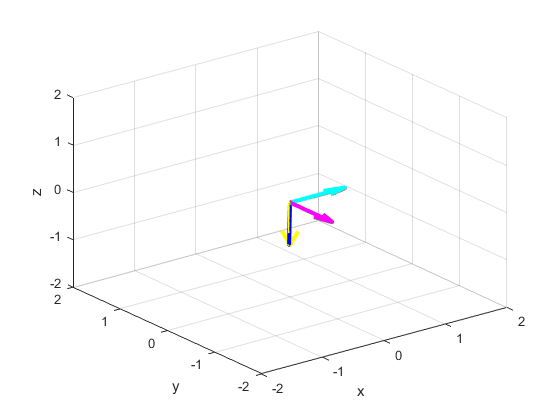

%%% Your code begins here

%Set an initial yaw so the x-Axis of world frame and smartphone frame are alligned at startup.
starting_rotation = 0; %[DEG]
initial_yaw = deg2rad(mobile_data.Orientation(1) + starting_rotation);

while(1)
    
    %Convert Yaw Roll and Pitch to RAD and calculate yaw in relation to initial_yaw
    yaw = initial_yaw-deg2rad(mobile_data.Orientation(1));

    %%% Your code ends here


    pitch = deg2rad(mobile_data.Orientation(2));
    roll = -deg2rad(mobile_data.Orientation(3));
    
    %Calculate R by multiplying rotation-matrices
    R = Rx(roll)*Ry(pitch)*Rz(yaw);
    
    %Apply Rotation to Smartphone Frame
    smartphone_frame = R*world_frame;
    
    %Plot smartphone frame and world frame
    plot_frames(smartphone_frame,smartphone_frame_origin,world_frame,world_frame_origin);
end

### We now have correctly calculated the Rotational Matrix R! This allows us to freely transform sensor values from the smartphone frame to the world frame! We will take advantage of this in the next livescript: smartphone_sensors.mlx 